## Computing constants

vmax = 12; %max velocity needed for shooting 10 m
s = 0.5; %stroke/length of the barrel [m]
w = 5e-3; %width of the channel [m]
m = 0.2; %mass of the carriage [kg]
t = ( 2 * s / vmax) % acceleration time [s]

t = 0.0833

a = vmax / t %acceleration [m/s^2]

a = 144

F = m * a %Force needed [N]

F = 28.8000

P = F * vmax %Max power needed [W]

P = 345.6000


d = 0.02; %pole-to-pole distance [m] (i.e. the distance between the centers of consecutive permenant magnets) 
xs = d * 4 / 3; %distance between 2 coils 
xstep = d * 0.66; %step size of each cycle 
cycle = [
    -1 0 1;
    0 -1 1;
    1 -1 0;
    1 0 -1;
    0 1 -1;
    -1 1 0; ]; % commutation cycle for 3 phase motor

mp = 1e2; %magnetic dipole permenant magnet
mc = 1e3; %magnetic dipole coils

mu0 = 4*pi*10^-7;

## Simulation of the linear induction motor

dt = 1E-3;
t_final = 0.2;

x_mag = [0:d:s] %locations of magnets

x_mag =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000


n_mag = length(x_mag); %number of magnets
magnetization = zeros(1,n_mag); %magnetization
for i = 1: n_mag
    magnetization(i) = rem(i,2) - 1;
end
magnetization(magnetization==0) = 1

magnetization =      1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1



t = [0:dt:t_final] %time variable

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


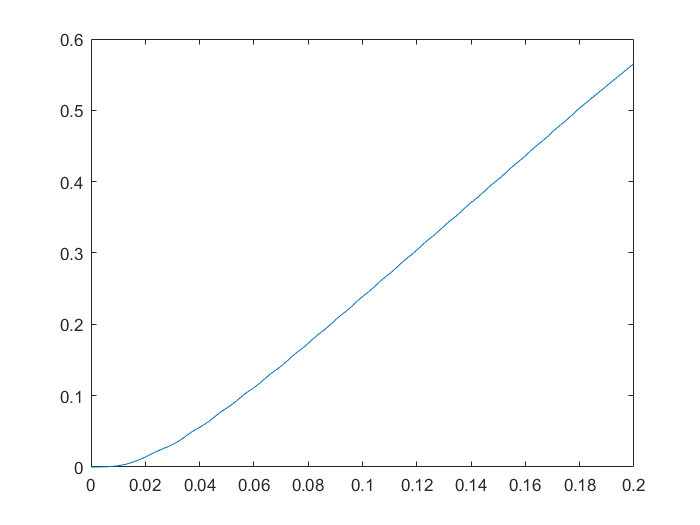

%starting from -dt because the first time step in the loop is computing the
%initial conditions
L = length(t); %length of the data set

%preallocating space
%comutator variables
c1 = zeros(1,L);
c2 = zeros(1,L);
c3 = zeros(1,L);


r1 = zeros(n_mag,L);
r2 = zeros(n_mag,L);
r3 = zeros(n_mag,L);

x = zeros(1,L); %locations of the rear of the carriage;
a = zeros(1,L);
v = zeros(1,L);
Fnet = zeros(1,L);
for i = 1 : L - 1
    step =  abs(rem(floor(x(i) / xstep),6))+ 1; %which step in the commutation cycle we are
    com = cycle(step,:); %loading the current commutation
    
    %current state of the coils
    if x <= s
        c1(i) = com(1);
        c2(i) = com(2);
        c3(i) = com(3);
    end
    
    %distances between coils and magnets
    r1(:,i) = x_mag - x(i); 
    r2(:,i) = x_mag - x(i) + 1*xs;%added coil offset
    r3(:,i) = x_mag - x(i) + 2*xs;
    


    %computing the forces from each coil
    theta1 = atan(2*r1(:,i)/w); %angle between the magnet and the coil
    direction1 = magnetization'.* c1(i); %computing wether the magnet and coil are repulsing or atracting
    r1_real = sqrt(r1(:,i).^2 + (w^2)/4); %the distance with the gap taken into account
    Fm1 = 2 * sum( (direction1 * 3 * mu0 * mp * mc ./ (2*pi* (r1_real) )  ).* sin(theta1));
    
    theta2 = atan(2*r2(:,i)/w); %angle between the magnet and the coil
    direction2 = magnetization'.* c2(i); %computing wether the magnet and coil are repulsing or atracting
    r2_real = sqrt(r2(:,i).^2 + (w^2)/4); %the distance with the gap taken into account
    Fm2 = 2 * sum( (direction2 * 3 * mu0 * mp * mc ./ (2*pi* (r2_real) )  ).* sin(theta2));
    
    theta3 = atan(2*r3(:,i)/w); %angle between the magnet and the coil
    direction3 = magnetization'.* c3(i); %computing wether the magnet and coil are repulsing or atracting
    r3_real = sqrt(r3(:,i).^2 + (w^2)/4); %the distance with the gap taken into account
    Fm3 = 2 * sum( (direction3 * 3 * mu0 * mp * mc ./ (2*pi* (r3_real) )  ).* sin(theta3));
    
    Fnet(i) = Fm1 + Fm2 + Fm3;
    a(i) = Fnet(i) / m;
    v(i+1) = v(i) + a(i) * dt;
    x(i+1) = x(i) + v(i)*dt; %computing new x position
    
end


plot(t,x)

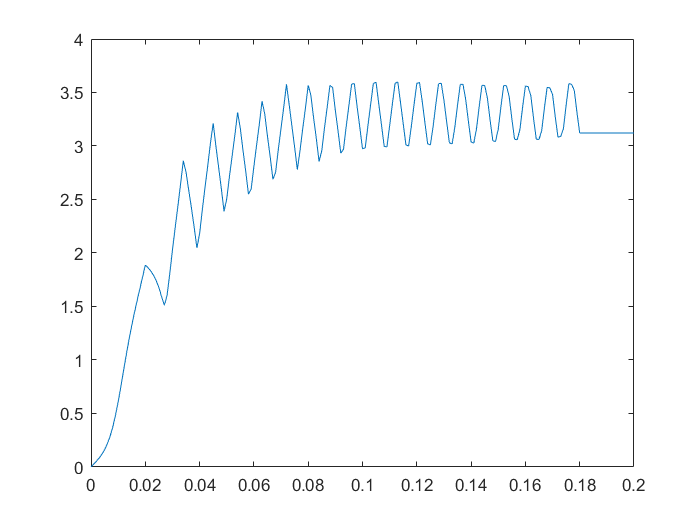

plot(t,v)

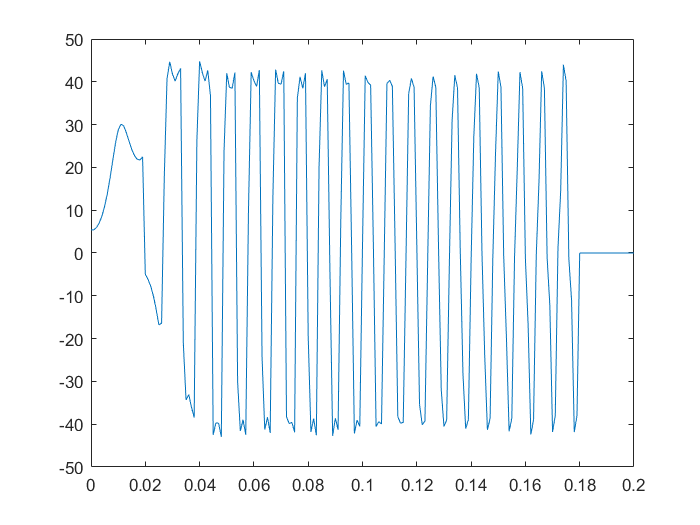

plot(t,Fnet)

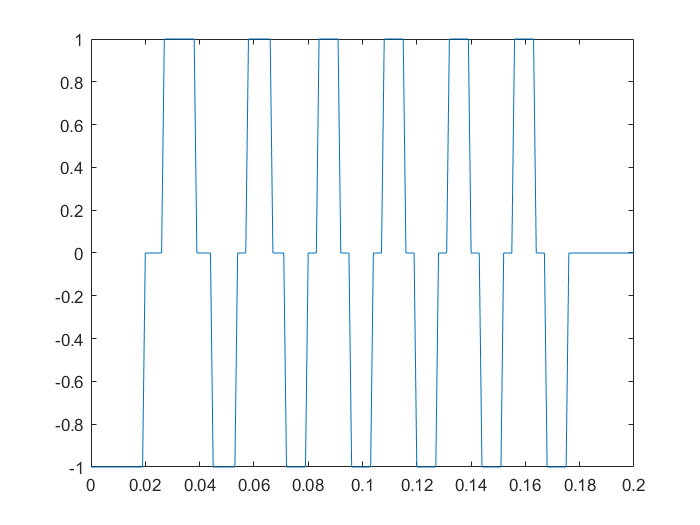

plot(t,c1)